# **Alexnet face recognition**

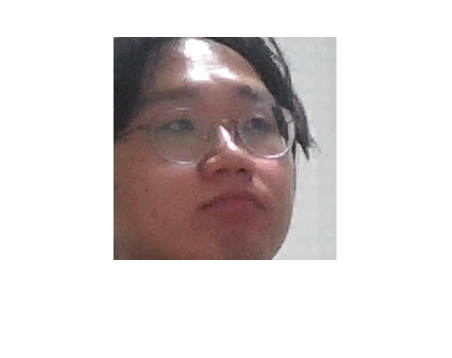

cam=webcam;
faceDetector=vision.CascadeObjectDetector;
c=100;
temp=0;
while true
    video_frame=cam.snapshot;
    bboxes =step(faceDetector,video_frame);
    if(sum(sum(bboxes))~=0)
    if(temp>=c)
        break;
    else
    video_face=imcrop(video_frame,bboxes(1,:));
    video_face=imresize(video_face,[224 224]);
    filename=strcat(num2str(temp),'.bmp');
    imwrite(video_face,filename);
    temp=temp+1;
    imshow(video_face);
    drawnow;
    end
    else
        imshow(video_frame);
        drawnow;
    end
end

model=alexnet;
layers=model.Layers;
layers(23)=fullyConnectedLayer(1);
layers(25)=classificationLayer;
allImages=imageDatastore('Face_Recongnition_Database','IncludeSubfolders',true, 'LabelSource','foldernames');
opts=trainingOptions('sgdm','InitialLearnRate',0.001,'MaxEpochs',20,'MiniBatchSize',64);
FaceNet=trainNetwork(allImages,layers,opts);

단일 GPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０２　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜　　　　　　２０　｜　　　　　　２０　｜　　　　　００：００：１３　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 최대 Epoch가 완료되었습니다.


save FaceNet;

model2=resnet18;
model3 = googlenet

model3 =   DAGNetwork - 속성 있음:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


numClasses = 1

numClasses = 1

lgraph = layerGraph(model3);
lgraph

lgraph =   LayerGraph - 속성 있음:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'loss3-classifier',newFCLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);
allImages=imageDatastore('Face_Recognition_Database_Resnet','IncludeSubfolders',true, 'LabelSource','foldernames');
opts=trainingOptions('adam','InitialLearnRate',0.001,'MaxEpochs',20,'MiniBatchSize',32);
FaceResNet=trainNetwork(allImages,lgraph,opts);

단일 GPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０１　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜　　　　　　１７　｜　　　　　　５０　｜　　　　　００：００：３４　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜　　　　　　２０　｜　　　　　　６０　｜　　　　　００：００：４０　｜　　　　　１００．００％　｜　－０．００００ｅ＋００　｜　　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 최대 Epoch가 완료되었습니다.


save FaceResNet;

cam=webcam;
load FaceResNet;
faceDetector=vision.CascadeObjectDetector;
while true
    e=cam.snapshot;
    bboxes =step(faceDetector,e);
    if(sum(sum(bboxes))~=0)
      es=imcrop(e,bboxes(1,:));
      es=imresize(es,[224 224]);
      label=classify(FaceResNet,es);
      image(e);
      title(char(label));
      drawnow;
    else
        image(e);
        title('No Face Detected');
    end
end